# Wave Physical Modeling as PI Model

clear
close all
format compact
clc

addpath("functions/")

## Simulation Params

t_stop = 25;
wd = (2*pi/0.05)/10;

## Circuit Params

%% Given parameters
A               = 0.1;                 % wave amplitude [m]
T               = 1.5;                 % period [s]
diameter_LUPA   = 1;                   % m
Separation      = diameter_LUPA * 3;   % total line length to model [m]

% wave‐line params (for context)
rho = 1000;   g = 9.8;
w      = 2*pi/T;
lambda = g*T^2/(2*pi);                 % wavelength [m]

% design constraint: max length per π-block
per_pi_limit = lambda * 0.05;          % e.g. 5% of a wavelength

%% 1) Minimum number of π-sections required
N_pi = ceil( Separation / per_pi_limit );
% now each section will be <= per_pi_limit

%% 2) Recompute the actual section length to exactly fill Separation
per_pi_length = Separation / N_pi;

%% 3) Lumped‐π parameters for each section
ZC     = 2*w^3/(g^2*rho);              % characteristic impedance
Cl     = rho*g/(2*w^2);               
Ll     = 2*w^4/(rho*g^3);

z      = 1i*w*Ll;                      % series impedance per meter
y      = 1i*w*Cl;                      % shunt admittance per meter

Z_sec  = z * per_pi_length;            % series branch per section
Y_sec  = y * per_pi_length;            % shunt branch per section

L_lumped = Z_sec/(1i*w);               % L per π-section
C_lumped = Y_sec/(1i*w)/2;             % C per branch per π-section


L = L_lumped;
C = C_lumped;
SIL = ZC;
% Corrected
% Zp = Z*sinh(gamma*pi_length)/(gamma*pi_length);
% Yp = Y*tanh(gamma*pi_length/2)/(gamma*pi_length/2);
% L = Zp/(1i*w)
% C = Yp/(1i*w)/2


## LUPA Params

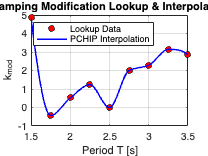

load('lupadata_spring2024_sparD1_14m.mat');

[hydro.float_mass, ...
    hydro.float_added_mass,...
    hydro.float_damping, ...
    hydro.float_stiffness, ...
    hydro.spar_mass, ...
    hydro.spar_added_mass,...
    hydro.spar_damping, ...
    hydro.spar_stiffness] = fn_get_lupa_params(w,lupadata);

ckt.C_add = hydro.float_added_mass;
ckt.C_m = hydro.float_mass;
ckt.C_M = ckt.C_add+ckt.C_m;
ckt.R_rad = 1/hydro.float_damping;
ckt.L_hs = 1/hydro.float_stiffness;
ckt.R_pto = 1/144;

%% Lookup‐table for damping modification to match experimental data
T_ref      = [1.5, 1.75, 2, 2.25, 2.5, 2.75, 3, 3.25, 3.5];  % period [s]
Mod_values = 1000 * [1.7, -0.15, 0.18, 0.43, 0.0001, 0.7, 0.8, 1.1, 1];  
B_ref      = 350;                                           % reference damping
k_mod      = Mod_values / B_ref;                           % normalized factors

%% Create a function handle for interpolation
%   Usage: k = k_mod_fun(T_query);
k_mod_fun = @(Tq) interp1(T_ref, k_mod, Tq, 'pchip', 'extrap');

%% Example: evaluate and plot over a finer grid
T_query = linspace(min(T_ref), max(T_ref), 200);   % was min(T), max(T)
k_query = k_mod_fun(T_query);

figure;
plot(T_ref, k_mod, 'ko','MarkerFaceColor','r','DisplayName','Lookup Data'); hold on;
plot(T_query, k_query, 'b-','LineWidth',1.5,'DisplayName','PCHIP Interpolation');
xlabel('Period T [s]');
ylabel('k_{mod}');
legend('Location','best');
grid on;
title('Damping Modification Lookup & Interpolation');



ckt.R_fric = 1/(350*(1+k_mod_fun(T)));

## Impulse response function of Excitation Force trasfer function

location = 'hydro/floatspar.h5'

location = 'hydro/floatspar.h5'

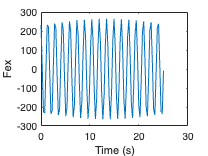


[IRF_t,ckt.FIR_causal, ckt.FIR_non_causal,Fex1_freq]=Excitation_FIR(location);
IRF_dt=IRF_t(2)-IRF_t(1);
ckt.FIR_combined = [ckt.FIR_non_causal; ckt.FIR_causal];
[~,ix_w] = min((lupadata.w-w).^2); 

F_ex_w = Fex1_freq(ix_w);
t=linspace(0,t_stop,100);
F_ts=real(A*F_ex_w*exp(1i*w*t));

figure;
plot(t,F_ts)
xlabel("Time (s)")
ylabel("Fex")

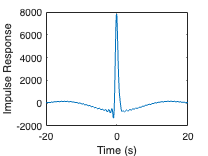


figure;
plot(IRF_t,ckt.FIR_combined');
xlabel("Time (s)")
ylabel("Impulse Response")


eta1 = A*sin(w*t);
Fex_conv = conv(ckt.FIR_combined,eta1);


convolution

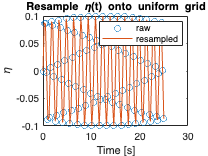

%% 0) Original irregular η‐series
t_eta_raw  = t;       % non-uniform time stamps [s]
eta_raw    = eta1;  % corresponding η(t)

%% 1) Build a uniform grid covering the same span
%    Pick dt as the median of your raw diffs to avoid outliers
dt    = median(diff(t_eta_raw));                 
t_eta = ( t_eta_raw(1) : dt : t_eta_raw(end) )';  % column

%% 2) Resample η onto that grid
%    Use pchip (or spline) for smoothness
eta = interp1(t_eta_raw, eta_raw, t_eta, 'pchip', 'extrap');

%% 3) (Optional) Plot to verify
figure;
plot(t_eta_raw, eta_raw, 'o', t_eta, eta, '-');
legend('raw','resampled');
xlabel('Time [s]');
ylabel('\eta');
title('Resample \eta(t) onto uniform grid');


%% Now t_eta and eta are uniform; you can proceed with IRF resampling & convolution

% e.g. IRF resampling:
t_irf_new = IRF_t(1) : dt : IRF_t(end);
irf_rs    = interp1(IRF_t, ckt.FIR_combined, t_irf_new, 'linear', 0);

% convolution (with dt factor)
y_conv = conv(eta, irf_rs, 'full') * dt;

% construct convolution time axis
t_conv = ( t_eta(1)+t_irf_new(1) ) : dt : ...
         ( t_eta(end)+t_irf_new(end) );


F_ex_approx = A(w_idx)*ddeta+B(w_idx)*deta+K*eta;

Unrecognized function or variable 'w_idx'.

Plotting the results

load("amplitude_reduction.mat")
V0 = data{2}.Values;
V1 = data{16}.Values;
V2 = data{28}.Values;

    % Define color palette
    colors.osu.orange = [243 115 33]/256;
    colors.osu.darkblue = [93 135 161]/256;
    colors.osu.lightblue = [156 197 202]/256;
    colors.osu.lightgray = [201 193 184]/256;
    colors.osu.darkgray = [171 175 166]/256;
    colors.osu.gold = [238 177 17]/256;
    colors.osu.lightbrown = [176 96 16]/256;
    colors.osu.red = [192 49 26]/256;
    colors.osu.green = [159 166 23]/256;
    colors.osu.purple = [98 27 75]/256;
    colors.osu.black = [0 0 0]/256;

figure;
plot(V0,'LineWidth', 2, 'Color', colors.osu.darkblue)
hold on
plot(V1,'LineWidth', 2, 'Color', colors.osu.green)
plot(V2,'LineWidth', 2, 'Color', colors.osu.red)
hold off
grid on
xlabel("Time (s)")
ylabel("Velocity (m/s)")
legend("Location 0","Location 1","Location 2")
xlim([0,25])
    ax = gca;
    ax.FontSize = 24 ;
    ax.XAxis.FontSize = 18 ;
    ax.YAxis.FontSize = 18 ;


## Interaction between Water and WEC 

Let's use simplified excitation force transfer function as an input to the WEC system $H(s) = A_ms^2 + B_{r}s + \frac{K_{hs}}{s}
$ where A,B, and K are hydrodynamic coefficients.

then,


$$F_{ex} (s) = \dot{\eta}(s) H(s) 


$$


where $F_{ex}
$ is excitation force, and $\dot\eta(s)$ is vertical velocity of water surface at the location.

**Power equality ***assume that no energy dissipation by heat


$$P_{ex} = F_{ex}v_{WEC} = \dot\eta Hv_{WEC}
$$



$$P_{ex} = P_{rad} + P_{pto} +P_{fric} = F_{rad}v_{WEC} + F_{pto}v_{WEC} + F_{pto}v_{WEC} \\
v_{WEC}(F_{rad}+F_{pto}+F_{fric}) = \dot\eta v_{WEC} H\\
F_{rad} = \dot\eta H - F_{pto} - F_{fric}$$


## Documentation

### General Waves

wave speed = wave length / wave period = wave length * wave frequency

wave speed = sqrt(elastic property / inertial property)


$$c = \lambda f = \lambda/T=\lambda \frac{\omega}{2 \pi}$$


### Electrical

For electrical, $c = \sqrt{\frac{1}{L_l C_l}}$ where Ll and Cl are per length.  It then follows that $\frac{\lambda^2}{T^2} = \frac{1}{L_l C_l}$Considering current as the through variable and voltage as the across variable, then the elastic property is 1/Ll and the inertial property is Cl.

### Water

For water, $c = \sqrt{\frac{g \lambda}{2 \pi}}$.  It then follows that $c = \sqrt{\frac{c 2 \pi g}{2 \pi \omega}}$  and


$$c = \sqrt{\frac{g^2}{\omega^2}} = \frac{g}{\omega}$$


Considering force as the through variable and speed as the across variable, the elastic property is $g^2$ and the inertial property is $\omega^2$.  

$C_l = \omega^2$ and $L_l = \frac{1}{g^2}$

Generalizing,

$L_l = \frac{1}{kg^2}$ and $C_l =k \omega^2$.

### PI Model

A PI model is good for distances about 5% of the wavelength.  Assuming a 100 meter wavelength, that's only 5 meters.

Assume Ll and Cl are per length.

Assume z is the series impedance per unit length.  Neglecting resistance, $z = j \omega L_l$

Assume y is the shunt admittance per unit length.  Neglecting resistance, $y = j \omega C_l$


$$Z_C = \sqrt{\frac{z}{y}}$$



$$\gamma = \sqrt{yz}$$


PI model: $Z = zl$ and $Y = yl$.

The two admittances are split Y/2.  Therefore each branch capacitance is $C_l l/2$.  The series inductance is $L_l l$

To make the PI model match the true 2-port:

$Z' = Z \sinh(\gamma l)/(\gamma l)$ and $Y' = Y \tanh((\gamma l)/2)/((\gamma l) / 2)$

A PI model is valid so long as $\sinh(\gamma l) = \gamma l$ and $\tanh((\gamma l)/2) = (\gamma l) / 2$

### Set LC based on Power

For monochromatic waves, the wave power is

$P_{wave} = \frac{\rho g^2}{32 \pi} H^2 T = \frac{\rho g}{16 \pi} c H^2 =  \frac{\rho g^2}{16 \omega} H^2$ [W/m]

where $H = 2A$ and $\eta = A \sin\left(\frac{2 \pi}{T} t\right) = A \sin\left(\omega t\right)$

Assuming voltage is $\dot{\eta}$ and current is force.


$$\dot{\eta} = A \omega \cos\left(\omega t \right)$$


Then


$$\left( \frac{A \omega}{\sqrt{2}}\right)^2 / Z_c = P_{wave}$$



$$Z_c = \frac{2 \omega^3}{g^2 \rho}$$



$$Z_C = \sqrt{\frac{z}{y}} = \sqrt{\frac{L_l}{C_l}} = \frac{1}{kg\omega} = \frac{2 \omega^3}{g^2 \rho}$$


## Characteristic Impedance Taylor Expansion (Even-Order)

Express the wave characteristic impedance $Z_C(\omega )$ using even powers of ω, by expanding around ω₀ up to 4th order.

### Taylor Expansion Expression

The original impedance is:


$$Z_C(\omega) = \frac{2\omega^3}{g^2 \rho}$$


Rewriting this as a function of $\( x = \omega^2 \)$, we get:


$$Z_C(x) = \frac{2x^{3/2}}{g^2 \rho} \quad \text{where } x = \omega^2$$


The Taylor expansion of $\( x^{3/2} \)
$ around $\( x_0 = \omega_0^2 \)$ gives:


$$x^{3/2} \approx x_0^{3/2} + \frac{3}{2}x_0^{1/2}(x - x_0) + \frac{3}{8}x_0^{-1/2}(x - x_0)^2$$


Substituting back $\( x = \omega^2 \)$, we obtain:


$$Z_C(\omega) \approx A_0 + A_2 \omega^2 + A_4 \omega^4$$


### **Coefficients**

The coefficients are:


$$A_0 = -\frac{\omega_0^3}{4 g^2 \rho}
$$



$$
A_2 = \frac{3\omega_0}{2 g^2 \rho}
$$



$$
A_4 = \frac{3}{4 g^2 \rho \omega_0}$$


### Final Approximation Expression

Thus, the even-order approximation of $\( Z_C(\omega) \)$ becomes:


$$Z_C(\omega) \approx -\frac{\omega_0^3}{4 g^2 \rho} + \frac{3\omega_0}{2 g^2 \rho} \omega^2 + \frac{3}{4 g^2 \rho \omega_0} \omega^4$$


% % Parameters
% omega0 = 0.125 * 2*pi; % expansion point (rad/s)
% 
% % Frequency range
% omega = linspace(0, 2*omega0, 500);
% 
% % Original characteristic impedance
% Z_true = (2 .* omega.^3) ./ (g^2 * rho);
% 
% % Taylor expansion coefficients (even-order around omega0)
% A0 = -omega0^3 / (4 * g^2 * rho);
% A2 = (3 * omega0) / (2 * g^2 * rho);
% A4 = 3 / (4 * g^2 * rho * omega0);
% 
% % Taylor approximation
% Z_approx = A0 + A2 .* omega.^2 + A4 .* omega.^4;
% 
% tf_SIL = [A4 0 -A2 0 A0];
% 
% % Define the transfer function as the inverse
% sys = tf(1, tf_SIL);
% poles=pole(sys);
% % Bode plot
% figure;
% bode(sys);
% grid on;
% title('Bode Plot of 1 / (A4 s^4 - A2 s^2 + A0)');
% 
% % Plotting
% figure
% plot(omega, Z_true, 'LineWidth', 2)
% hold on
% plot(omega, Z_approx, '--', 'LineWidth', 2)
% xlabel('Frequency (rad/s)', 'Interpreter', 'latex')
% ylabel('$Z_C(\omega)$', 'Interpreter', 'latex')
% legend('Original', 'Even-order Taylor Approx.', 'Location', 'northwest')
% title('Comparison of Characteristic Impedance and Taylor Approximation')
% grid on
% hold off

% % Define notch filter parameters
% omega_notch = abs(imag(poles(4)));    % rad/s
% zeta = 0.1;            % narrow notch
% 
% % Numerator and denominator
% Num = [1 0 omega_notch^2];
% Den = [1 2*zeta*omega_notch omega_notch^2];
% 
% % Define the notch filter transfer function
% notch_filter = tf(Num, Den);
% 
% % Plot notch filter Bode plot
% figure
% bodeplot(notch_filter);
% title('Notch Filter at pole rad/s');
% grid on;
% 
% % Apply filter to the system
% filtered_sys = notch_filter * sys;
% Num=cell2mat(filtered_sys.Numerator);
% Den=cell2mat(filtered_sys.Denominator);
% 
% % Bode plot comparison
% figure
% bodeplot(sys, filtered_sys);
% legend("Original", "Filtered");
% title('Bode Plot: Original vs. Notch Filtered');
% grid on;


$$k = \frac{g \rho}{2 \omega^4}$$



$$L_l = \frac{1}{kg^2} = \frac{2 \omega^4}{\rho g^3}$$



$$C_l = k \omega^2 = \frac{g \rho}{2 \omega^2}$$


## Frequency Dependence


$$L_l = \frac{1}{kg^2} = \frac{2 \omega^4}{\rho g^3} = -\frac{2}{\rho g^3} s^4$$



$$C_l = k \omega^2 = \frac{g \rho}{2 \omega^2} = -\frac{g \rho}{2} \frac{1}{s^2}$$


% %s = tf('s');
% %G_true = -g*rho/2 / (s^2);  % True system
% 
% % Full frequency vector (rad/s)
% w_full = logspace(log10(2*pi/10), log10(2*pi/1), 1000);
% 
% k = g*rho./(2*w_full.^4);
% G_true = 1./(k.*g.*w_full);
% 
% % Generate frequency response with noise
% % [mag_full, phase_full] = bode(G_true, w_full);
% % mag_full = squeeze(mag_full);
% % phase_full = squeeze(phase_full);
% mag_full = abs(G_true);
% phase_full = angle(G_true);
% 
% % Add measurement noise
% noise_level = 0.05;
% mag_noisy = mag_full .* (1 + noise_level * randn(size(mag_full)));
% phase_noisy = phase_full + 2 * randn(size(phase_full));
% 
% H_full = mag_noisy .* exp(1j * phase_noisy * pi/180);
% 
% data = idfrd(H_full, w_full, 0, 'FrequencyUnit', 'rad/s');
% G = tfest(data, 4)  % 2nd order model
% G2 = fitfrd(data,4)
% 
% [num1, den1] = invfreqs(H_full, w_full, 4, 3);
% G3 = tf(num1, den1);
% 
% bode(G,G2,G3,data)

